# Crashcourse in Matlab - Part VI: User defined Functions

There are several basic ways in which you can program Matlab. The most important ones are classical functions and scripts. Both functions and scripts have the file extension ".m", but there are important differences. 

But first ...

# Scripts

Our main code file will tyically be a script. A script is just a collection of Matlab commands saved as a ".m" file that perform some more or less useful task ...

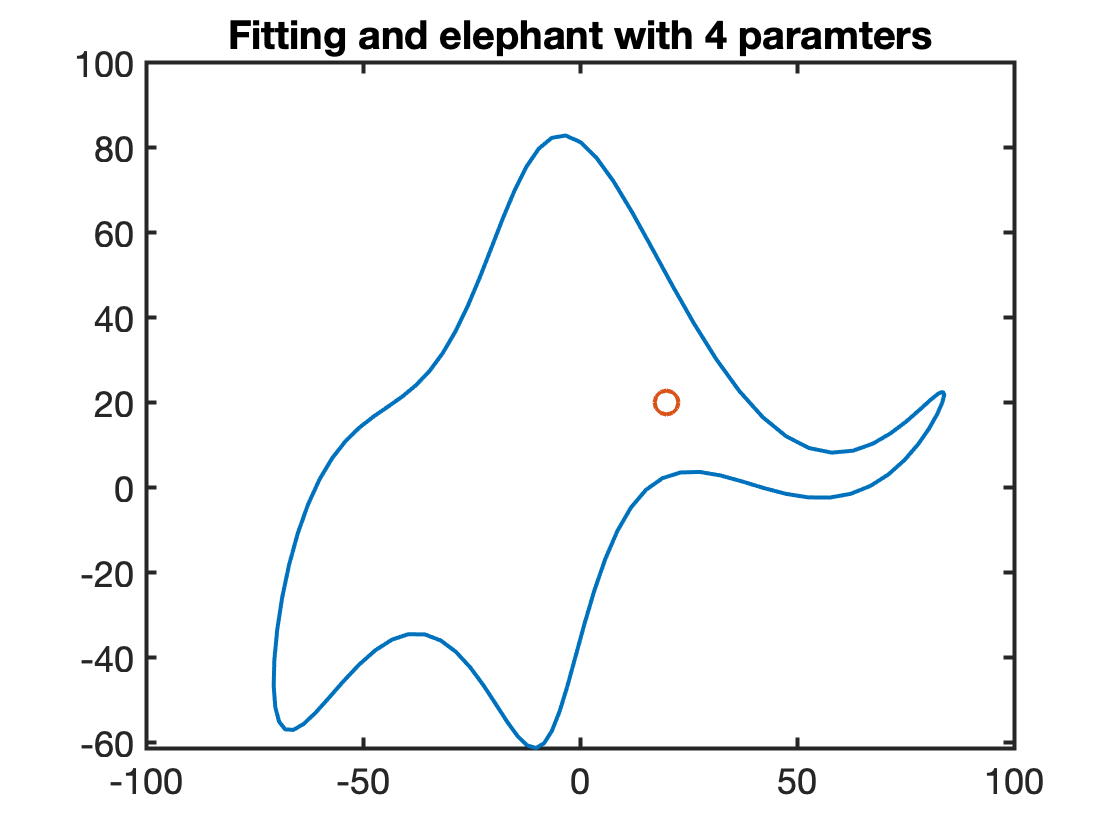

clear all, close all
set_defaults

% Marc's great script
Ax = [-60  0   0 0   0];
Bx = [-30  8 -10 0   0];
Ay = [  0  0  12 0 -14];
By = [ 50 18   0 0   0];

t = linspace(0,2*pi,1e2);
x = 0*t; y = x;
for k = 1:5
    x = x + Ax(k)*cos(k*t) + Bx(k)*sin(k*t);
    y = y - Ay(k)*cos(k*t) - By(k)*sin(k*t);
end
plot(x,y,'-'), hold on
plot(20,20,'o'), hold off
title('Fitting and elephant with 4 paramters')

However is you would like to plot many elephants and change their size, location and orientation in a consistent manner ... Then it makes sense to write a function that automates this task. Here the function takes into account location, size, color and the direction the elephant faces.

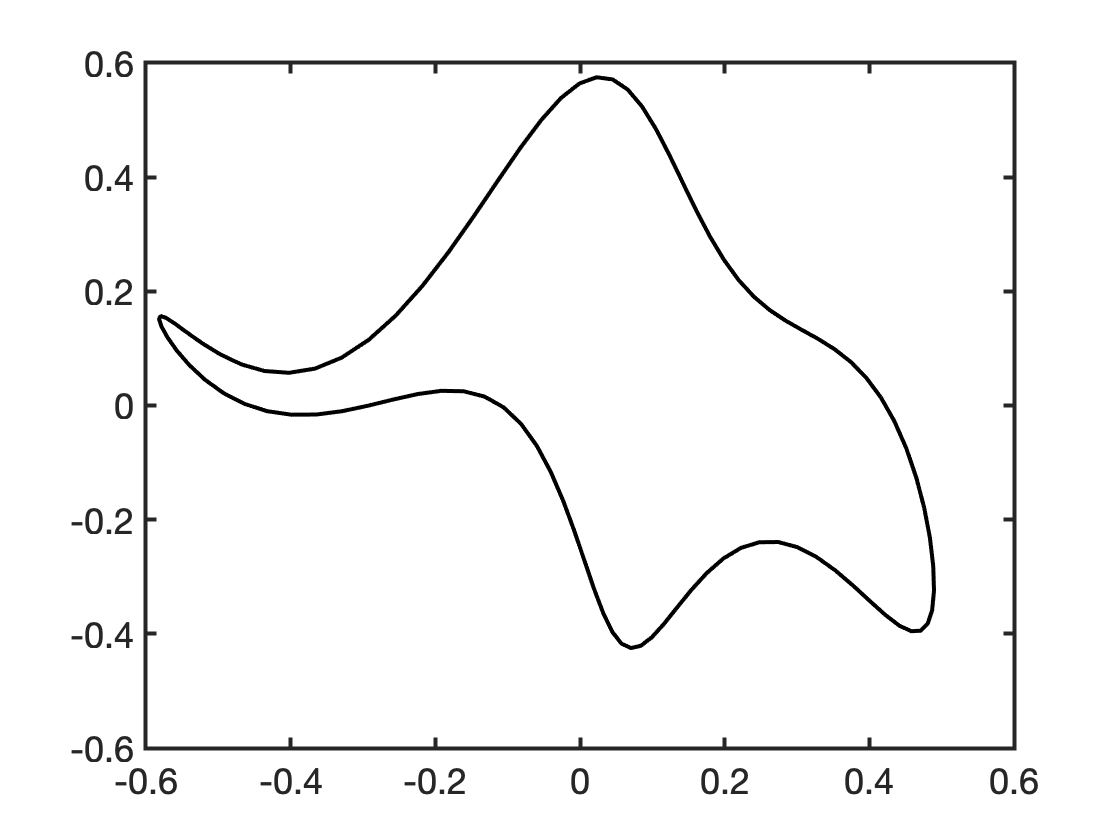

plot_elephant(0,0,'l',1,[0 0 0])

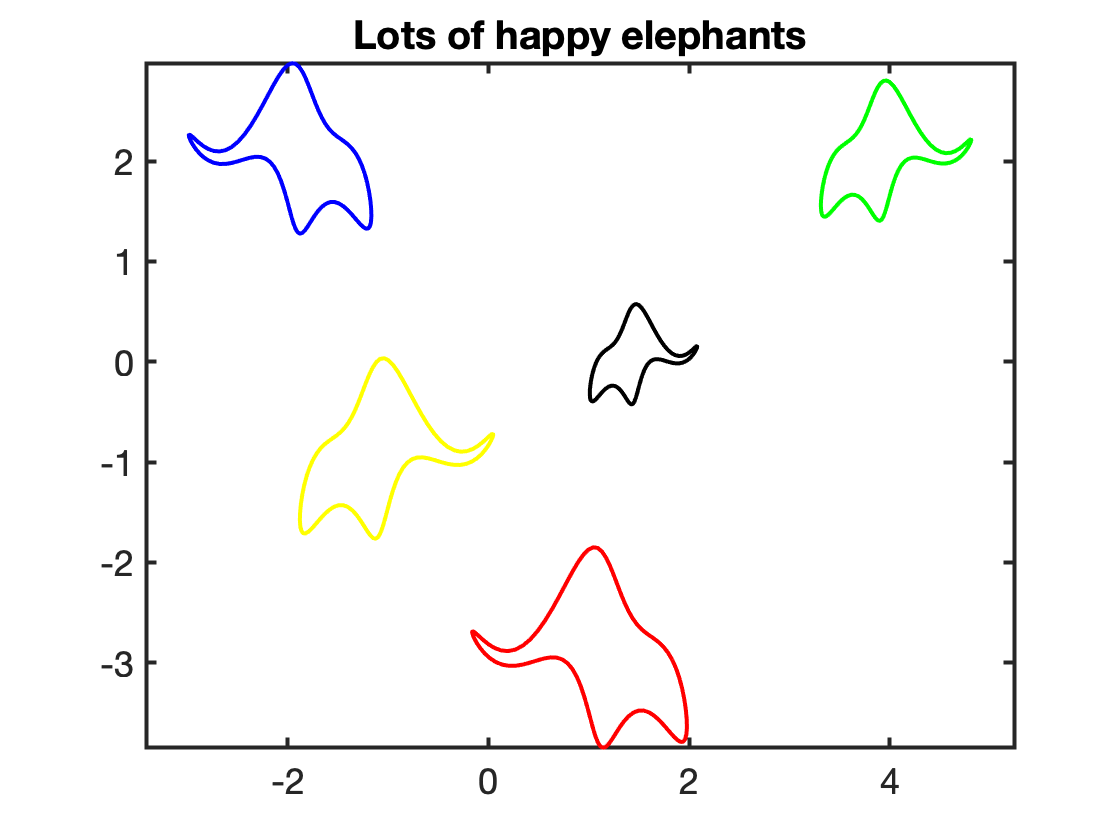

x0 = [ 1 4 -2 -1  1.5];
y0 = [-3 2  2 -1 0];
dir_vec = ['l','r','l','r','r'];
scale_vec = [2 1.4 1.7 1.8 1];
col_vec =['r';'g';'b';'y';'k'];
for i = 1:length(x0)
    plot_elephant(x0(i),y0(i),dir_vec(i),scale_vec(i),col_vec(i,:)), hold on
end
axis equal
title('Lots of happy elephants')
hold off

Functions avoid mistakes if the same portion of code is re-used many times and they improve the readability of the code - at least if the function names are useful.

The big difference between scripts and functions is scope, i.e., the visibility of variables. A *script* sees **any** **variable** that may be defined in your work space a *function* only see **variables** **passed** to it explicitly. 

A if you run the exactly same script twice it could do different things, because you have updated the variables it uses in the work space! That's why it is good practice to start any script with the command "clear all", to make sure that the script only used variables created by the scrpt itself.

In contrast a function only sees the variables you pass to it and the program that calls a function knows nothing about the variables inside a function, unless you pass them out as an output argument. A common error is to forget to pass a variable to a function!

In this class we will used scripts for the overall 'driver' of the simulation and functions for everything else.

# Function ettiquette (for this class)

Functions are by definition thought to be reused, by others or by yourself. Therefore, you should document functions in such a way that it is easy/possible for other/yourself to understand how to use it. In this class, we will use a standard function header that names author, date, input, output and gives a short description and **an example function call**. See the example below. 

function [] = plot_elephant(x0,y0,dir,scale,col)
% author: Marc Hesse
% date: 17 Jan 2018
% Description: Plots an elephant with four complex parameters
%              following the paper by Meyer et al. (2010),
%              Am. J. Phys., 78(�6), p. 648-649
% Input: x0, y0 = scalars that define center of mass
%        dir = string that is either 'l' or 'r' and
%              defined the direction the elephant is looking
%        scale = elephant height
%        col = 1 by 3 row vector defining the color
% Output: None
% Example function call:
%
% plot_elephant(0,0,'l',1,[0 0 0])

Ax = [-60  0   0 0   0];
Bx = [-30  8 -10 0   0];
Ay = [  0  0  12 0 -14];
By = [ 50 18   0 0   0];

t = linspace(0,2*pi,1e2);
x = 0*t; y = x;
for k = 1:5
    x = x + Ax(k)*cos(k*t) + Bx(k)*sin(k*t);
    y = y - Ay(k)*cos(k*t) - By(k)*sin(k*t);
end
% rescale 
Dy = max(y) - min(y);
y = scale*y/Dy; x = scale*x/Dy;
% reflect
if strcmp(dir,'l')
    x = -x;
end
% shift
x = x0 + x; y = y0 + y;

plot(x,y,'-','color',col)
end

In homeworks you will be asked to to write a variety of functions. Typically the function header is given so you know what you need to do. **Never ever change the function header!** Otherwise your function will not cooperate with the rest of the program you are supposed to write.

## Auxillary function definitions

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end
